# Filtros

## Importar

Desde osciloscopio Rigol

%Señales del generador
wave_sqr = readmatrix("data/cuadrada.CSV"); %mV
wave_sin = readmatrix("data/senoidal.CSV"); %mV
N = length(wave_sin);
fs = 1/2E-06 %Hz;

fs = 500000


%Señales con ruido
noise_sqr = readmatrix("data/DS0011.CSV");
noise_sin = readmatrix("data/DS0010.CSV");
fs_noise = 1/1.000E-04 %Hz

fs_noise = 10000

N_noise = length(noise_sin)

N_noise = 4000

Desde la grabación de audio

%Demen un audio porfa

%audio_sqr = audioread()
%audio_sin = audioread()

Señal del filtro resonante

res_filter = readmatrix("data/scope_csv_27_0.csv");
N_res = length(res_filter);
fs_res = 1/res_filter(1,1);
res_filter = res_filter(:,2);

## Visualizar en tiempo

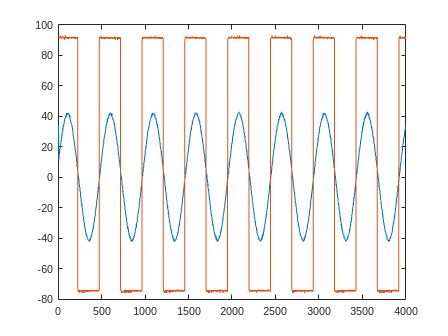

figure
plot(wave_sin)
hold on
plot(wave_sqr)
hold off

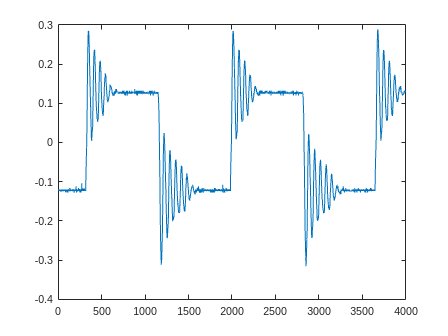


figure
plot(res_filter)

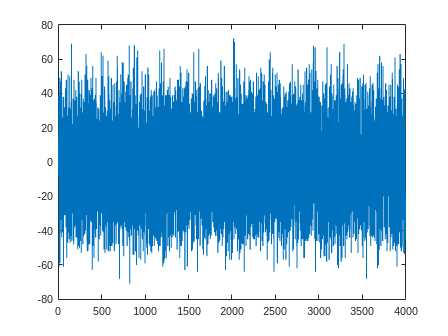


figure
plot(noise_sqr)

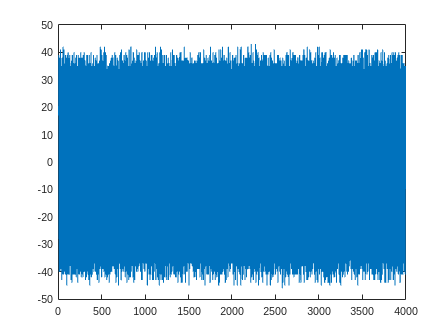


figure
plot(noise_sin)

Escuchar 

%

## Espectro

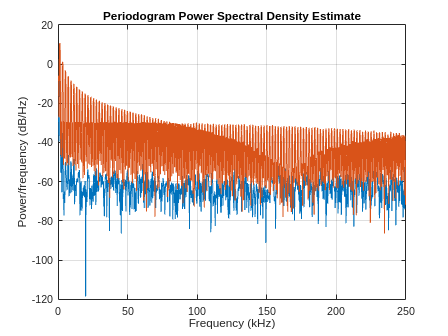

periodogram([wave_sin wave_sqr],flattopwin(N),N,fs)

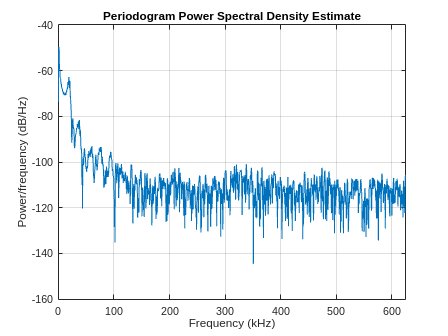

periodogram(res_filter,flattopwin(N_res),N_res,fs_res)

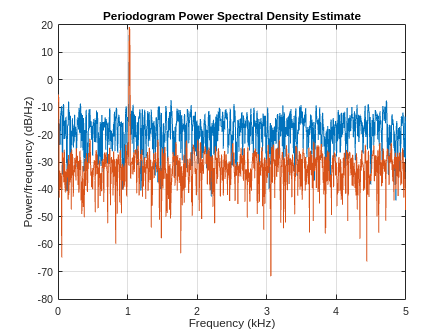

periodogram([noise_sqr noise_sin],flattopwin(N_noise),N_noise,fs_noise)

## Find peaks

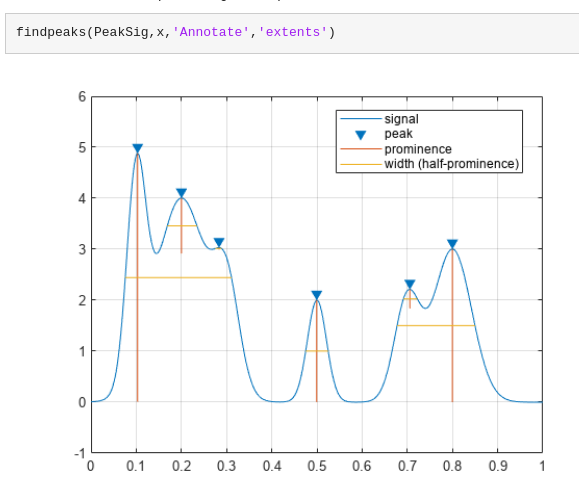

## Step response